## ENGI9804 Image Processing and Applications Lab4 

### Calculating the moment invariants

1. Download the grayscale test image (image.png), calculate moments.m, and Moment invariants.m files from D2L under Lab 4 and save them in the MATLAB working directory. Read the files and understand the implementation of calculating the seven invariant moments.

2. Read the image, obtain the size of the image and pad the image by one-fourth the image size in all directions with zeros. Use this as the basis for next steps (referred to as Im1).

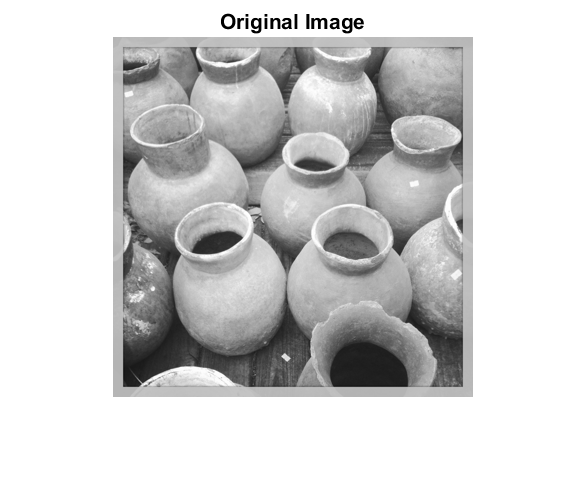

image=imread('image.png'); % read the image\
% Get the dimensions of the image.  
% numberOfColorBands should be = 1.
[M, N, numberOfColorBands] = size(image);
if numberOfColorBands > 1
  % the image is colorful
  % Convert it to gray scale
  image = rgb2gray(image);
end
figure, imshow(image), title("Original Image");

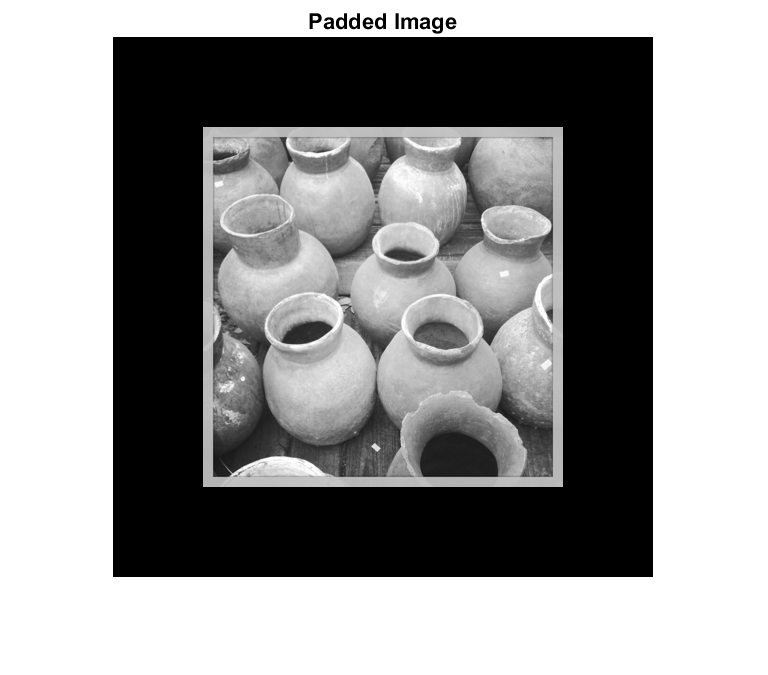

% Xt, Yt are one-fourth of the original image
Xt = M/4;
Yt = N/4;
Im1 = padarray(image, [Xt, Yt], 0); % pad the image
figure, imshow(Im1), title("Padded Image");

3. Create spatial transformation matrix T1 for translation as follows:

T1 = maketform('affine', [1 0 0; 0 1 0; Xt Yt 1]);

Use the above transformation matrix T1 and perform the transformation as follows:

Im2 = imtransform(Im1, T1, 'XData',[1 size(Im1,1)], 'YData',[1 size(Im1,2)]);

Display the translated image Im2;

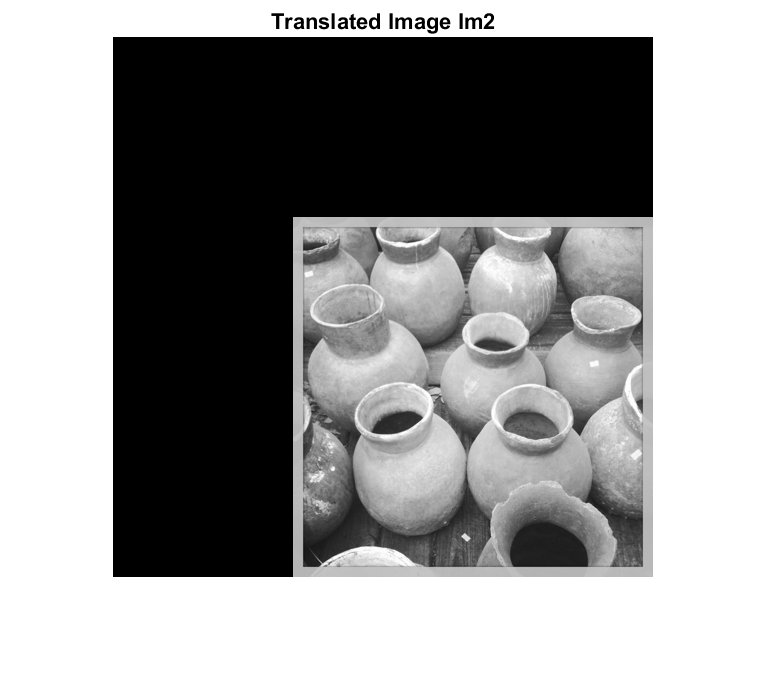

figure, imshow(Im2), title("Translated Image Im2");

4. Create spatial transformation matrix T2 for scaling to 0.5 (of original size) as follows:

T2 = maketform('affine', [0.5 0 0; 0 0.5 0; 0 0 1]);

Use the above transformation matrix T2 and perform the transformation as follows:

Im3 = imtransform(Im1, T2, 'XData',[1 size(Im1,1)], 'YData',[1 size(Im1,2)]);

Display the translated image Im3;

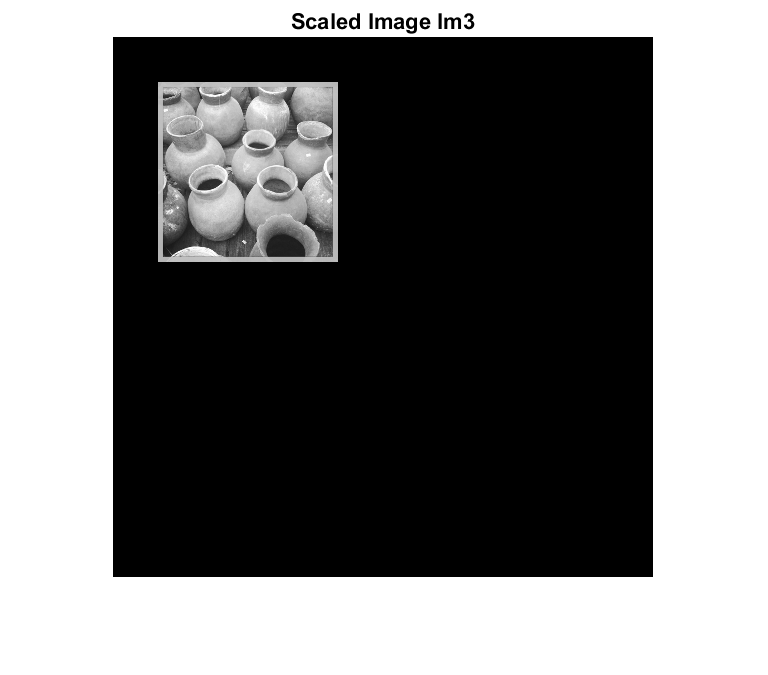

figure, imshow(Im3), title("Scaled Image Im3");

5. Create spatial transformation matrix T3 to rotate the image by 45 degrees as follows:

T3 = maketform('affine', [cos(pi/4) sin(pi/4) 0; -sin(pi/4) cos(pi/4) 0; 0 0 1]);

Use the above transformation matrix T3 and perform the transformation as follows:

Im4 = imtransform(Im1, T3, 'XData',[-269 size(Im1,1)-270], 'YData',[+111 size(Im1,2)+110]);

Display the translated image Im4;

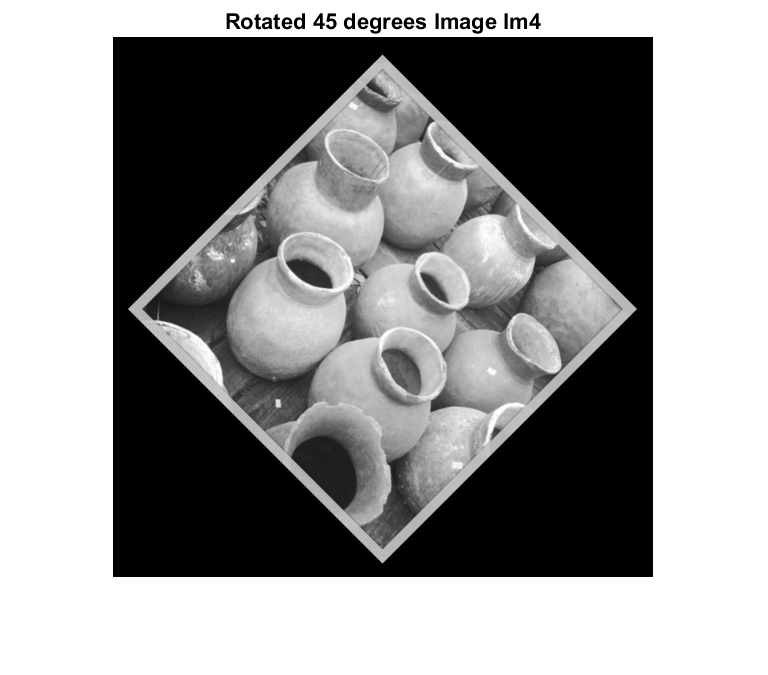

figure, imshow(Im4), title("Rotated 45 degrees Image Im4");

6. Create spatial transformation matrix T4 for rotating the image 90 degrees as follows:

T4 = maketform('affine', [cos(pi/2) sin(pi/2) 0; -sin(pi/2) cos(pi/2) 0; 0 0 1]);

Use the above transformation matrix T4 and perform the transformation as follows:

Im5 = imtransform(Im1, T4, 'XData',[-539 size(Im1,1)-540], 'YData',[1 size(Im1,2)]);

Display the translated image Im5;

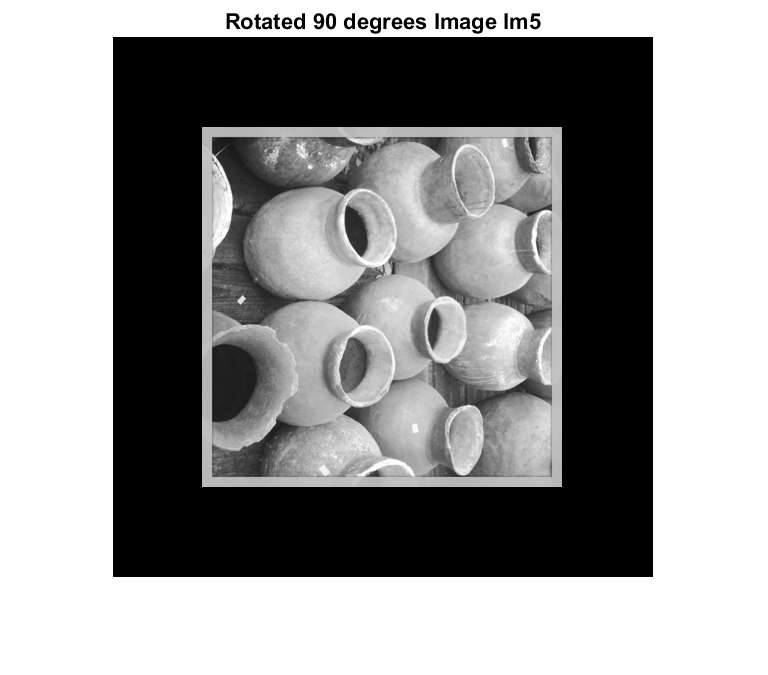

figure, imshow(Im5), title("Rotated 90 degrees Image Im5");

7. Flip the original image Im1 from left to right using following command and generate image Im6.

Im6=flipdim(Im1,2);

Display the mirrored image Im6;

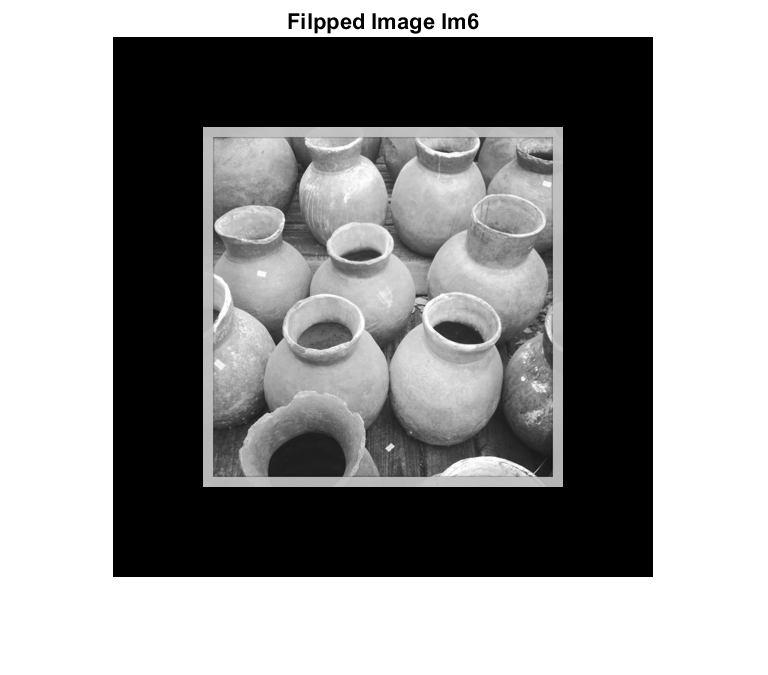

figure, imshow(Im6), title("Filpped Image Im6");

8. The downloaded matlab file Moment_invariant.m contains a function Moment invariant(), which calls to another function named as calculate moments. Collectively, these functions calculate the moment invariants.

Use the function Moment invariant() and pass the images created from step 2 to step 7 (Im1-Im6) from the command line. For example, the following line will display the moment invariants calculated for Im1: Moment_invariants(Im1)

Im = cell(6,1);
Im_moment = cell(6,1);
% calculate 7 moments for each image
for i = 1:6
    Im{i} = eval(sprintf('Im%d', i));
    Im_moment{i} = Moment_invariants(Im{i});
end

Moment_Invariants =    -0.5738   -4.2405   -4.4618   -4.5262   -9.1160    6.6464    9.2440


Moment_Invariants =    -0.5738   -4.2405   -4.4618   -4.5262   -9.1160    6.6464    9.2440


Moment_Invariants =    -0.5735   -4.2480   -4.4569   -4.5111   -9.1012    6.6353    9.2014


Moment_Invariants =    -0.5738   -4.2397   -4.4612   -4.5266   -9.1165    6.6465    9.2440


Moment_Invariants =    -0.5738   -4.2405   -4.4618   -4.5262   -9.1160    6.6464    9.2440


Moment_Invariants =    -0.5738   -4.2405   -4.4618   -4.5262   -9.1160    6.6464   -9.2440


### Discussion

1. You should include the MATLAB code and results in your lab report.

2. Discuss the values of the moment invariants computed for each image, including any similarities or differences. What do these similiarities or differences mean in terms of image features?

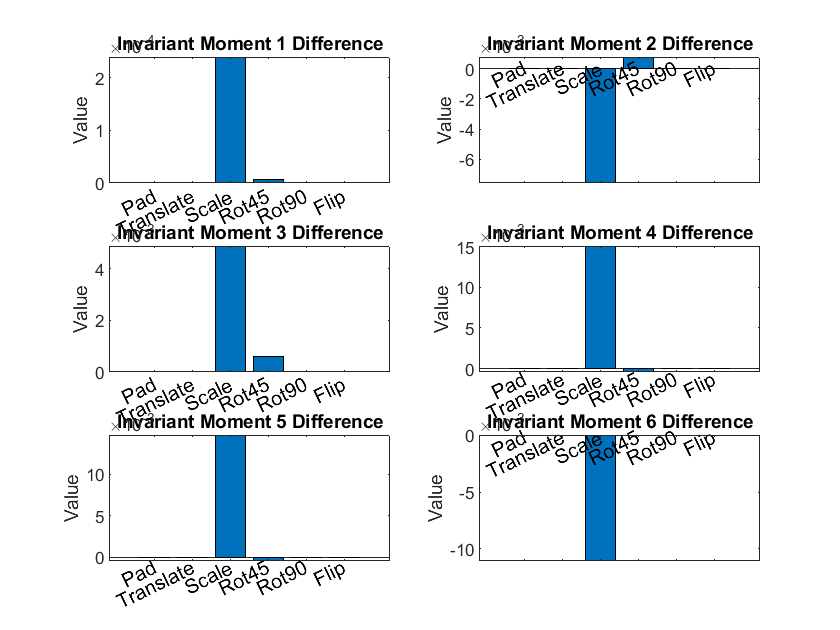

% Plot histogram
X = [1;2;3;4;5;6];
X_names = {'Pad', 'Translate', 'Scale', 'Rot45', 'Rot90', 'Flip'};
moment = cell(6,1);
for i = 1:6
    for j = 1:6
        moment{i}(j) = Im_moment{j}(i);
    end
end

figure; 
for i = 1:6
    subplot(3,2,i);
    bar(X,moment{i}-moment{i}(1));
    title(sprintf('Invariant Moment %d Difference', i));
    ylabel('Value');
    set(gca,'xticklabel',X_names);
    xtb = get(gca,'XTickLabel');% Get the handler of the abscissa axis label
    xt = get(gca,'XTick');% Get the handler of the abscissa axis scale
    yt = get(gca,'YTick'); % Get the handler of the ordinate axis scale       
    xtextp=xt;% The abscissa of each label placement position                 
    ytextp=-0.1*yt(3)*ones(1,length(xt));
    text(xtextp,ytextp,xtb,'HorizontalAlignment','right','rotation',26,'fontsize',10);
    set(gca,'xticklabel','');% Hide the original label
end

From the histograms, we could tell that most transformed figures have the same variant moments, except for scaling and rotating 45 degrees. Note that the abscissa axis label "Pad" represents the original image.  In other words, translating, rotating 90 degrees, and flipping don't change any variant moment. It makes sense since these three transforms don't change the distance from any pixel to the center. However, scaling will change every pixel's distance to the center. That's why the difference in scaling is the biggest. On the other side, the rotating 45 degrees may not change any pixel's moment. But because of the precision of Trigonometric functions, there will be some calculated error. That's why the difference between rotating 45 degrees is small.